# Atividade 1 2° Bimestre

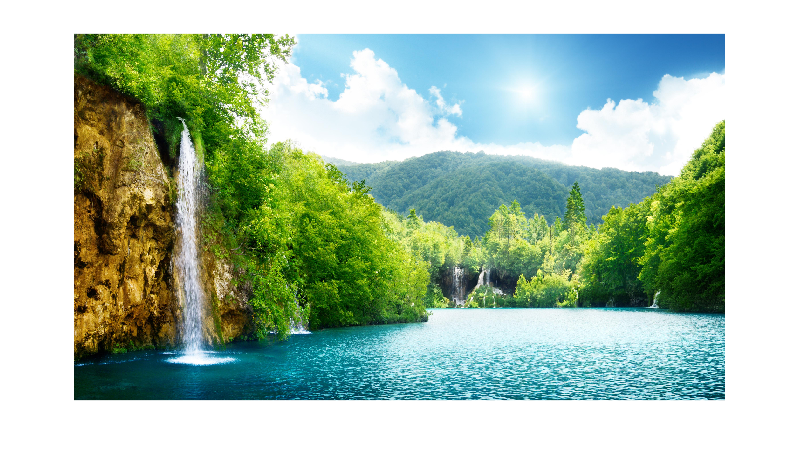

x = imread("imagem_natureza.png");
vet = [0.1 0.7 0.2];
imshow(x);

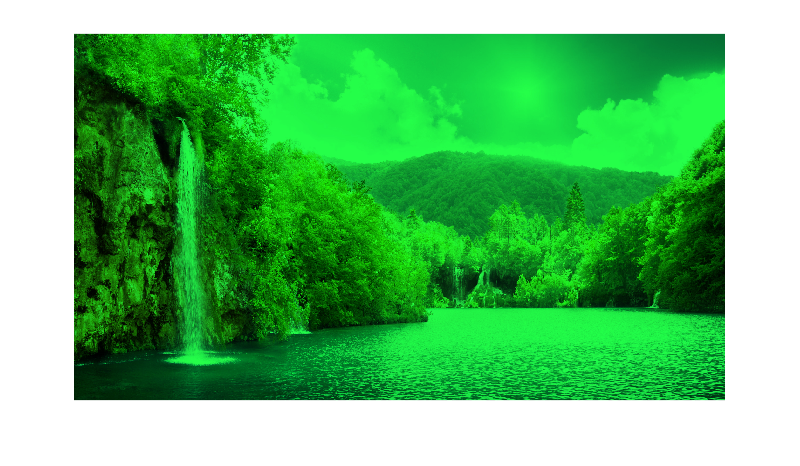

y = equaliza_cor(x,vet);
imshow(y);

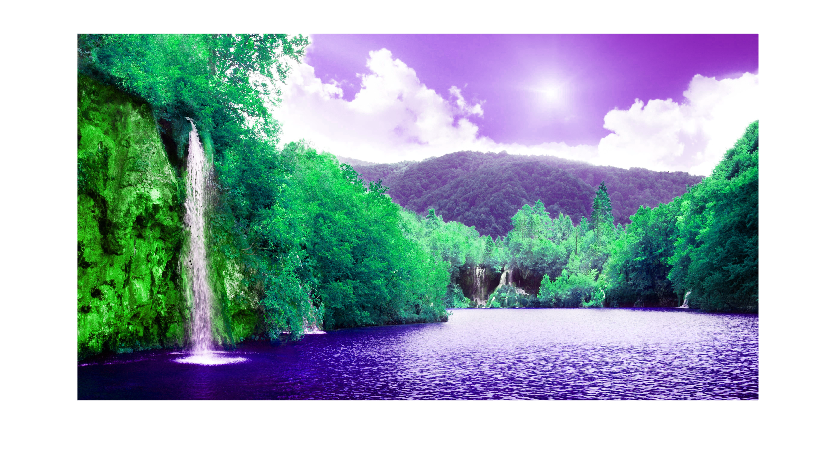

deslocamento = 0.2;
y = modif_ton(x,deslocamento);
imshow(y);

function y = equaliza_cor(img,rgb)
    x = double(img)/255;
    for i = 1 : 3
        x(:,:,i) = img(:,:,i)*rgb(i);
    end
    max_x = max(x(:));
    y = x/max_x;
end

function y = modif_ton(x,d)
    x_hsi = rgb2hsv(x);
    x_hsi(:,:,1) = x_hsi(:,:,1)+d;
    y = hsv2rgb(x_hsi);
end
